Филимонов Степан РЛ6-31

Лабараторная номер 5

Задача:

Необходимо отрисовать для электрона локализованного в одномерной  бесконечно глубокой яме 10 нм график пси функции от координаты (для  основного состояния и 24-го возбужденного). Сравнить графики полученный  на основе аналитического решения уравнения Шрёдингера с результатами  работы встроенной MATLAB-функции eig.

Фото задания:

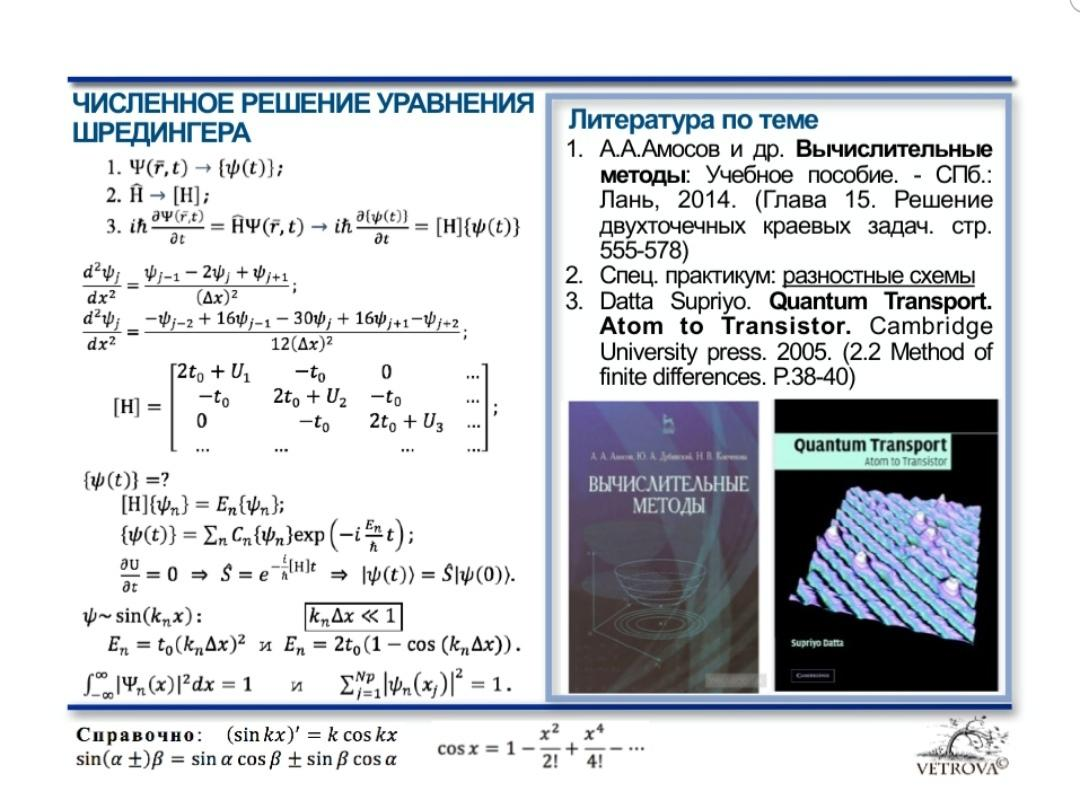

Теория:

**Квантовая яма с бесконечными стенками** — область пространства размером порядка длины волны де Бройля рассматриваемой частицы (хотя бы в одном направлении), вне которой потенциальная энергия *U* бесконечна. Иногда данную область называют «ящиком»

**Двухточечная краевая задача** - это задача отыскания решения  обыкновенного дифференциального уравнения или системы обыкно­венных дифференциальных уравнений на отрезке $а\le x\le б$, в которой дополнительные условия на решение налагаются в двух точках а и б - "краях" отрезка (отсюда - и название задачи). 

Решение:

Численное решение уравнения Шредингера(стационарного)


$$-\frac{\hbar }{2m}\Delta \psi \left(x\right)+U\left(x\right)\psi \left(x\right)=E\psi \left(x\right)$$


- 
$$\Psi \left(\bar{r,t} \right)\to \left\lbrace \psi \left(t\right)\right\rbrace$$


- $\hat{H} \to \left\lbrack H\right\rbrack$;

- 
$$i\hbar \frac{\partial }{\partial t}\Psi \left(\bar{r,t} \right)=\hat{H} \Psi \left(\bar{r,t} \right)\to i\hbar \frac{\partial }{\partial t}\left\lbrace \psi \left(t\right)\right\rbrace =\left\lbrack H\right\rbrack \left\lbrace \psi \left(t\right)\right\rbrace$$


Из


$$\left\lbrace \begin{array}{ll}
\psi_{i+1} =\psi_i +\Delta x\frac{d}{\mathrm{d}x}\psi_i +\frac{\Delta x^2 }{2!}\frac{d^2 }{\mathrm{d}x^2 }\psi_i +\frac{\Delta x^3 }{3!}\frac{d^3 }{\mathrm{d}x^3 }\psi_i +\frac{\Delta x^4 }{4!}\frac{d^4 }{\mathrm{d}x^4 }\psi_i +\ldotp \ldotp \ldotp  & \\
\psi_{i-1} =\psi_i -\Delta x\frac{d}{\mathrm{d}x}\psi_i +\frac{\Delta x^2 }{2!}\frac{d^2 }{\mathrm{d}x^2 }\psi_i -\frac{\Delta x^3 }{3!}\frac{d^3 }{\mathrm{d}x^3 }\psi_i +\frac{\Delta x^4 }{4!}\frac{d^4 }{\mathrm{d}x^4 }\psi_i +\ldotp \ldotp \ldotp  & 
\end{array}\right.$$


Получим:

$\frac{\psi_{i+1} -2\psi_i +\psi_{i-1} }{\Delta x^2 }=\frac{d^2 }{\mathrm{d}x^2 }\psi_i \Longrightarrow$ это трехточечная апроксимация оператора 2-ой производной , где


$$\textrm{dx}=\frac{L}{N_p +1}$$


Подставим его:


$$-\frac{\hbar }{2m}\left\lbrack \frac{\psi_{i+1} -2\psi_i +\psi_{i-1} }{\Delta x^2 }\right\rbrack +U_i \psi_i =E_i \psi_i$$


Матрицой этого уравнения будет

$\left\lbrack H\right\rbrack =\left\lbrack \begin{array}{cccc}
2x_0 +U_1  & -x_0  & 0 & \ldotp \ldotp \ldotp \\
-x_0  & 2x_0 +U_2  & -x_0  & \ldotp \ldotp \ldotp \\
0 & -x_0  & 2x_0 +U_3  & \ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp 
\end{array}\right\rbrack$, где $x_0$это константанта, равная $x_0 =\frac{\hbar^2 }{2m}*\frac{1}{\textrm{dx}}$,$U_i$ - матрица увеличивающая высоту, в нашей задаче = 0, по этому при вычислении учитывотся не будет

Аналитическое решение $\Upsilon =\sin \left(\pi \frac{\textrm{condition}}{L}x\right)$, следует из $k=\frac{\textrm{condition}*\pi }{L}$ и $\psi \left(x\right)=\textrm{Asin}\left(\textrm{kx}\right)$, в нашем случае $A=1$.

Код Matlab:

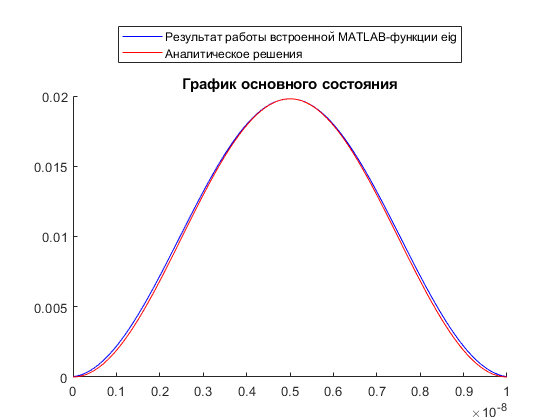

cla reset;
hold on;
L = 10*1e-9; 
Np = 100;
[Phk , Ek] = matrixSchrodinger(L, Np); %*(см. ниже)
X = linspace(0, L, Np);
plot(X, abs(Phk(1:end, 1)).^2,"Color",'blue');
plot(X, abs(Phkcondition(1, L, X, Np)).^2,"Color",'red'); %*(см. ниже)
title('График основного состояния');
legend('Результат работы встроенной MATLAB-функции eig','Аналитическое решения','Location',"northoutside");
hold off;

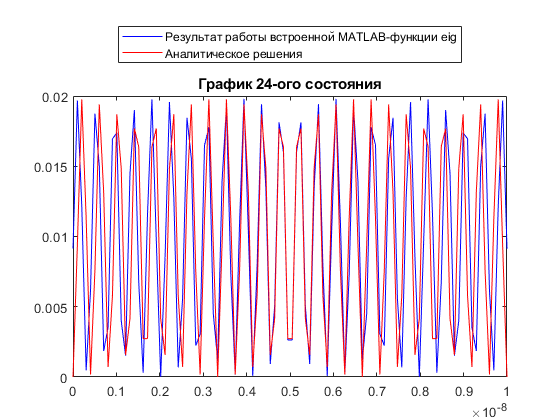

plot(X, abs(Phk(1:end, 24)).^2,"Color",'blue');
hold on;
plot(X, abs(Phkcondition(24, L, X, Np)).^2,"Color",'red'); %*(см. ниже)
title('График 24-ого состояния');
legend('Результат работы встроенной MATLAB-функции eig','Аналитическое решения','Location',"northoutside");

prt = 0;
for c = 1:100
  prt = prt + abs(Phk).^2.*(L*1e-9/101);
end
prt

prt = 	1.0e+-18 *

    0.0002    0.0008    0.0017    0.0030    0.0047    0.0067    0.0091    0.0119    0.0150    0.0184    0.0221    0.0261    0.0303    0.0349    0.0397    0.0447    0.0499    0.0553    0.0609    0.0666    0.0724    0.0783    0.0844    0.0904    0.0965    0.1026    0.1087    0.1147    0.1207    0.1266    0.1324    0.1380    0.1435    0.1488    0.1539    0.1588    0.1635    0.1679    0.1720    0.1759    0.1794    0.1827    0.1856    0.1882    0.1904    0.1922    0.1937    0.1949    0.1956    0.1960
    0.0008    0.0030    0.0067    0.0119    0.0184    0.0261    0.0349    0.0447    0.0553    0.0666    0.0783    0.0904    0.1026    0.1147    0.1266    0.1380    0.1488    0.1588    0.1679    0.1759    0.1827    0.1882    0.1922    0.1949    0.1960    0.1956    0.1937    0.1904    0.1856    0.1794    0.1720    0.1635    0.1539    0.1435    0.1324    0.1207    0.1087    0.0965    0.0844    0.0724    0.0609    0.0499    0.0397    0.0303    0.0221    0.0150    0.0091    0.0047

datetime('now')

ans = datetime
   02-Dec-2021 09:30:05


*Функция создания графика: 

function y = Phkcondition(n, L, X, Np)
 dx = sqrt((L/(Np+1)));
 r = sqrt(2/L);
 y = r.*sin((pi*n/L)*X).*dx;
end

function [Phk, Ee] = matrixSchrodinger(L, Np)
 load("constans.mat","m0","hbar");
 x0 = (hbar^2)/((2*m0*L)/Np+1);
 H = zeros(Np);
 H(1, 1) = 2 * x0;
 H(1, 2) = -x0;
 for r = 2:Np
   for c = 1:Np
     if and(and(r ~= 1, r ~= Np),r == c)
       H(r, c) = 2 * x0;
       H(r, c - 1) = -x0;
       H(r, c + 1) = -x0;
     end
   end
 end
 H(Np, Np) = 2 * x0;
 H(Np, Np - 1) = -x0;
 [Phk, Ee] = eig(H); % вернем диагональную матрицу
end